## Espace de solutions suivant une trajectoire et qui respecte les butées articulaires et qui évite les singularitées du robot

**Recuperation des solutions calculées dans le fichier ***Config_Robot_Redondant_Point*

On définit tout d'abord les variables du code puis l'espace de solutions sans conditions de filtrage pour atteindre le point cible est recupéré pour ensuite afficher les differentes configuration articulaires possibles en radian

% Charger les solutions depuis le fichier
load('solutionstraj.mat');
final_results(:, 2:6) = rad2deg(final_results(:, 2:6));

% Afficher les résultats finaux
%disp('Résultats finaux (en degrés) :');
%disp(final_results);

% Convertir les angles en radians et ajuster les angles à l'intervalle [-180, 180]
final_results(:, 2:6) = mod(final_results(:, 2:6)+ 180, 360) - 180;

% Afficher les résultats finaux en degrés ajustés
disp('Résultats finaux (en degrés ajustés) :');

Résultats finaux (en degrés ajustés) :



fprintf('| %-7s | %-9s | %-9s | %-9s | %-9s | %-9s | %-11s | %-11s |\n', 'Point', 'Theta1', 'Theta2', 'Theta3', 'Theta4', 'Theta5', 'X_calculé', 'Y_calculé');

| Point   | Theta1    | Theta2    | Theta3    | Theta4    | Theta5    | X_calculé   | Y_calculé   |


disp('__________________________________________________________________________________________________________________');

__________________________________________________________________________________________________________________


for i = 1:size(final_results, 1)
    fprintf('| %-7d | %-9.4f | %-9.4f | %-9.4f | %-9.4f | %-9.4f | %-11.4f | %-11.4f |\n', final_results(i,1), final_results(i,2:6), final_results(i,7:8));
end

| 1       | -42.4290  | 52.4646   | -2.3917   | -23.5677  | 49.6093   | 10.0000     | -0.0000     |
| 1       | -37.3502  | 38.1952   | 11.8885   | -28.7336  | 55.7759   | 10.0000     | 0.0000      |
| 1       | -19.6674  | 47.1656   | -40.9696  | -18.9194  | 56.7609   | 10.0000     | -0.0000     |
| 1       | 41.2759   | -58.6411  | 14.3331   | -26.1034  | 48.2695   | 10.0000     | 0.0000      |
| 1       | -8.9957   | 39.7278   | -44.4320  | -24.7769  | 52.8866   | 10.0000     | 0.0000      |
| 1       | -40.1524  | 35.2383   | 21.7243   | -24.0766  | 44.8987   | 10.0000     | -0.0000     |
| 1       | -4.9298   | -12.4647  | 50.3665   | -63.2216  | 59.8467   | 10.0000     | 0.0000      |
| 1       | -27.5075  | 47.7580   | -22.5594  | -29.6870  | 62.8481   | 10.0000     | 0.0000      |
| 1       | -29.4709  | 45.3207   | -15.0542  | -30.9126  | 64.8801   | 10.0000     | -0.0000     |
| 1       | -24.9181  | 20.4396   | 36.7955   | -60.9938  | 57.6052   | 10.0000     | -0.0000     |


disp('__________________________________________________________________________________________________________________');

__________________________________________________________________________________________________________________


## Filtrage des solutions

### Enlever de l'espace les solutions qui ne respectent pas les butées des angles d'articulation et qui sont des positions singulières

Cette partie tri notre espace de solutions, en fonction des butées de chaque articulations et des positions de singularitées. De cette manière, nous pouvons observer dans la table ci-dessous les configurations (en gras), qui respectent bien ces deux conditions.

Ainsi, on a dans la derniere table le resultat final de notre espace de travail qui repond aux differentes conditions de filtrage des solutions 

disp('Butées de chaque theta:')

Butées de chaque theta:


% Chargement de la matrice butee à partir du fichier .mat
load('butee.mat'); % Charge la matrice butee à partir du fichier butee.mat
disp(butee);

   -20    90
   -95    95
   -90    90
   -90    90
   -90    90




% Tri des solutions qui respectent les butees
trisolution = all(final_results_deg >= butee(:, 1)' & final_results_deg <= butee(:, 2)', 2);

% Vérifier les singularités
singularite = check_singularities(deg2rad(final_results(:, 2:6)), a1, a2, a3, a4, a5);

% Ajouter l'information de singularité comme une colonne supplémentaire
final_results_with_singularities = [final_results, singularite];

% Tableau pour stocker les résultats finaux
resultats_finaux = [];


% Mise en evidence des configurations qui respectent les butees et la non sing parmi
% toutes les solutions
disp('Configurations possibles du robot en respectant les butees et sans singularites:');

Configurations possibles du robot en respectant les butees et sans singularites:


fprintf('| %-7s | %-9s | %-9s | %-9s | %-9s | %-9s | %-9s | %-9s | %-9s |\n', 'Point', 'Theta1', 'Theta2', 'Theta3', 'Theta4', 'Theta5', 'X_calculé', 'Y_calculé', 'Singularité');

| Point   | Theta1    | Theta2    | Theta3    | Theta4    | Theta5    | X_calculé | Y_calculé | Singularité |


disp('_____________________________________________________________________________________________________________________');

_____________________________________________________________________________________________________________________


for i = 1:size(final_results_deg, 1)
    if trisolution(i) && ~singularite(i)
        fprintf('| %-7d | %-9.2f | %-9.2f | %-9.2f | %-9.2f | %-9.2f | %-9.0f | %-9.0f | %-9d |\n', final_results(i, 1), final_results_deg(i, :), final_results(i, 7), final_results(i, 8), singularite(i));
        % Ajouter la solution filtrée au tableau des résultats finaux
        resultats_finaux = [resultats_finaux; final_results(i, 1), final_results_deg(i, :), final_results(i, 7:8), singularite(i)];
    else
        fprintf('| %-7.0d | %-9.2f | %-9.2f | %-9.2f | %-9.2f | %-9.2f | %-9.0f | %-9.0f | %-9d |\n', final_results(i,1), final_results(i,2:6), final_results(i,7:8), singularite(i));
    end
end

| 1       | -42.43    | 52.46     | -2.39     | -23.57    | 49.61     | 10        | -0        | 0         |
| 1       | -37.35    | 38.20     | 11.89     | -28.73    | 55.78     | 10        | 0         | 0         |


| 1       | -19.67    | 47.17     | -40.97    | -18.92    | 56.76     | 10        | -0        | 0         |
| 1       | 41.28     | -58.64    | 14.33     | -26.10    | 48.27     | 10        | 0         | 0         |
| 1       | -9.00     | 39.73     | -44.43    | -24.78    | 52.89     | 10        | 0         | 0         |


| 1       | -40.15    | 35.24     | 21.72     | -24.08    | 44.90     | 10        | -0        | 0         |


| 1       | -4.93     | -12.46    | 50.37     | -63.22    | 59.85     | 10        | 0         | 0         |


| 1       | -27.51    | 47.76     | -22.56    | -29.69    | 62.85     | 10        | 0         | 0         |
| 1       | -29.47    | 45.32     | -15.05    | -30.91    | 64.88     | 10        | -0        | 0         |
| 1       | -24.92    | 20.44     | 36.80     | -60.99    | 57.61     | 10        | -0        | 0         |
| 1       | -33.99    | 29.85     | 19.57     | -30.75    | 57.04     | 10        | 0         | 0         |
| 1       | -49.47    | 49.07     | 9.00      | -1.31     | 22.31     | 10        | 0         | 0         |
| 1       | -30.32    | 30.77     | 16.73     | -42.65    | 64.33     | 10        | 0         | 0         |
| 1       | -32.62    | 31.12     | 18.82     | -38.26    | 60.62     | 10        | -0        | 0         |
| 1       | -20.45    | 54.63     | -21.64    | -25.10    | -16.98    | 10        | 0         | 0         |
| 1       | -41.51    | 39.05     | 18.99     | -25.21    | 45.03     | 10        | -0        | 0         |
| 1       | -35.73    | 52.8

| 1       | -12.84    | -6.66     | 49.68     | -51.33    | 56.66     | 10        | -0        | 0         |


| 1       | -32.47    | 28.69     | 23.64     | -39.37    | 58.57     | 10        | 0         | 0         |


| 1       | -11.71    | 25.27     | 0.84      | -63.18    | 69.53     | 10        | 0         | 0         |


| 1       | -31.25    | 7.22      | 43.22     | 1.87      | 5.11      | 10        | 0         | 0         |
| 1       | -43.90    | 41.82     | 14.68     | -16.17    | 39.81     | 10        | 0         | 0         |


| 1       | 6.76      | 16.42     | -18.06    | -55.90    | 49.52     | 10        | 0         | 0         |
| 1       | 12.21     | -30.34    | 38.83     | -57.76    | 67.33     | 10        | -0        | 0         |


| 1       | -32.52    | 17.57     | 44.33     | -35.46    | 38.74     | 10        | 0         | 0         |
| 1       | -42.41    | 63.34     | -28.93    | -2.56     | 38.02     | 10        | 0         | 0         |
| 1       | -35.44    | 46.48     | 2.61      | -41.19    | 58.83     | 10        | 0         | 0         |


| 1       | -18.82    | 2.27      | 52.87     | -56.04    | 49.44     | 10        | 0         | 0         |
| 1       | -19.57    | 2.39      | 44.50     | -44.96    | 56.08     | 10        | 0         | 0         |
| 2       | -4.39     | 42.22     | -20.76    | -16.88    | -34.25    | 10        | 1         | 0         |
| 2       | -19.41    | 50.17     | -36.98    | -13.93    | 56.91     | 10        | 1         | 0         |


| 2       | -31.53    | 53.22     | -18.31    | -13.97    | 52.96     | 10        | 1         | 0         |
| 2       | -33.25    | 49.93     | 6.94      | -39.85    | 51.48     | 10        | 1         | 0         |


| 2       | -19.36    | 14.16     | 49.17     | -55.73    | 45.64     | 10        | 1         | 0         |


| 2       | -31.50    | 30.86     | 30.05     | -31.70    | 44.29     | 10        | 1         | 0         |
| 2       | -28.96    | 33.69     | 32.44     | -50.30    | 47.48     | 10        | 1         | 0         |


| 2       | -12.73    | 15.23     | 36.51     | -66.24    | 61.55     | 10        | 1         | 0         |
| 2       | -9.41     | 35.17     | -9.10     | -56.06    | 65.52     | 10        | 1         | 0         |
| 2       | -10.03    | 35.18     | -13.75    | -48.85    | 69.29     | 10        | 1         | 0         |


| 2       | -29.86    | 51.68     | -9.29     | -31.12    | 57.11     | 10        | 1         | 0         |
| 2       | -27.85    | 54.88     | -33.86    | -2.32     | 49.17     | 10        | 1         | 0         |
| 2       | -20.85    | 14.07     | 37.24     | -37.33    | 53.45     | 10        | 1         | 0         |
| 2       | -33.28    | 45.15     | 10.76     | -34.87    | 52.59     | 10        | 1         | 0         |
| 2       | -30.44    | 40.43     | 4.29      | -23.56    | 57.16     | 10        | 1         | 0         |


| 2       | -0.25     | 40.75     | -54.19    | -12.55    | 43.11     | 10        | 1         | 0         |
| 2       | 12.55     | -14.86    | 36.21     | -72.06    | 67.12     | 10        | 1         | 0         |
| 2       | 12.46     | -21.58    | 43.07     | -65.33    | 65.75     | 10        | 1         | 0         |


| 2       | -42.58    | 62.68     | -24.30    | 25.45     | 5.63      | 10        | 1         | 0         |


| 2       | -3.33     | -6.44     | 50.85     | -62.20    | 57.70     | 10        | 1         | 0         |
| 2       | 12.52     | -34.24    | 52.66     | -44.63    | 53.59     | 10        | 1         | 0         |


| 2       | -36.59    | 50.13     | 11.62     | -35.41    | 45.59     | 10        | 1         | 0         |


| 2       | -1.60     | -5.40     | 57.14     | -72.70    | 46.58     | 10        | 1         | 0         |
| 2       | -2.38     | 37.18     | -11.16    | -27.31    | -31.12    | 10        | 1         | 0         |
| 2       | 21.50     | 10.71     | -26.97    | -44.73    | 37.14     | 10        | 1         | 0         |


| 2       | -29.06    | 36.10     | 10.67     | -27.41    | 58.01     | 10        | 1         | 0         |
| 2       | -39.05    | 50.86     | 0.61      | -11.19    | 40.62     | 10        | 1         | 0         |
| 2       | -29.93    | 31.47     | 31.65     | -41.36    | 47.51     | 10        | 1         | 0         |
| 2       | -35.01    | 56.04     | -11.30    | -20.16    | 49.36     | 10        | 1         | 0         |


| 2       | 9.94      | -22.94    | 47.10     | -59.56    | 63.40     | 10        | 1         | 0         |
| 3       | -13.17    | 42.31     | -3.16     | -50.80    | 64.04     | 10        | 2         | 0         |
| 3       | -2.31     | 28.59     | 28.69     | -53.28    | -20.33    | 10        | 2         | 0         |
| 3       | 18.32     | 25.54     | -45.28    | -26.90    | 45.70     | 10        | 2         | 0         |


| 3       | -20.89    | 22.80     | 40.82     | -38.91    | 41.81     | 10        | 2         | 0         |


| 3       | -13.61    | 45.00     | -23.07    | -24.87    | 64.88     | 10        | 2         | 0         |
| 3       | -4.95     | 16.72     | 47.62     | -76.04    | 37.71     | 10        | 2         | 0         |


| 3       | -27.63    | 42.51     | 18.36     | -35.35    | 48.16     | 10        | 2         | 0         |


| 3       | 12.42     | 31.12     | -40.28    | -33.31    | 50.45     | 10        | 2         | 0         |


| 3       | -25.12    | 48.72     | -21.13    | 5.01      | 46.03     | 10        | 2         | 0         |
| 3       | -25.03    | 50.30     | -4.60     | -29.37    | 55.98     | 10        | 2         | 0         |


| 3       | -18.01    | 41.91     | -2.36     | -37.31    | 65.22     | 10        | 2         | 0         |
| 3       | -15.05    | 50.88     | -40.65    | -1.06     | 52.09     | 10        | 2         | 0         |
| 3       | 17.16     | 13.32     | -5.16     | -65.51    | 58.52     | 10        | 2         | 0         |


| 3       | -24.51    | 21.33     | 44.52     | -20.54    | 18.67     | 10        | 2         | 0         |


| 3       | 35.04     | -52.56    | 32.86     | -14.92    | 48.91     | 10        | 2         | 0         |
| 3       | 3.99      | 37.46     | -41.70    | -25.81    | 58.40     | 10        | 2         | 0         |
| 3       | -13.27    | 52.76     | -40.31    | -11.33    | 52.96     | 10        | 2         | 0         |
| 3       | 15.56     | -16.75    | 56.56     | -75.80    | 46.69     | 10        | 2         | 0         |


| 3       | -25.76    | 21.76     | 33.19     | 6.15      | 3.47      | 10        | 2         | 0         |
| 3       | -24.25    | 32.04     | 29.46     | -36.43    | 47.01     | 10        | 2         | 0         |


| 3       | -18.66    | 49.80     | -50.25    | 59.32     | -17.92    | 10        | 2         | 0         |
| 3       | 14.32     | -32.62    | 52.24     | -30.90    | 46.87     | 10        | 2         | 0         |


| 3       | -30.98    | 42.80     | 4.70      | 0.71      | 34.02     | 10        | 2         | 0         |


| 3       | -10.07    | -1.58     | 52.40     | -26.27    | 32.22     | 10        | 2         | 0         |
| 3       | -17.60    | 6.61      | 43.24     | 4.12      | 1.59      | 10        | 2         | 0         |


| 3       | -24.28    | 54.22     | -40.89    | 29.28     | 25.39     | 10        | 2         | 0         |
| 3       | -24.91    | 43.66     | -9.70     | -3.13     | 50.32     | 10        | 2         | 0         |


| 3       | 19.52     | 17.64     | -8.44     | -31.20    | -29.16    | 10        | 2         | 0         |


| 3       | -21.09    | 15.65     | 43.43     | -18.50    | 25.43     | 10        | 2         | 0         |


| 3       | 1.31      | 34.98     | 6.09      | -44.47    | -21.20    | 10        | 2         | 0         |
| 4       | 10.93     | 40.55     | -72.69    | 50.00     | -15.70    | 9         | 3         | 0         |
| 4       | 18.32     | 23.71     | -0.96     | -30.89    | -36.43    | 9         | 3         | 0         |
| 4       | 51.06     | -44.40    | 42.97     | -34.82    | -29.85    | 9         | 3         | 0         |
| 4       | 2.55

| 4       | -23.61    | 52.80     | -26.77    | 33.91     | 11.75     | 9         | 3         | 0         |


| 4       | -19.33    | 38.44     | -2.40     | 5.00      | 41.51     | 9         | 3         | 0         |
| 4       | 28.16     | 8.25      | 5.21      | -32.06    | -38.41    | 9         | 3         | 0         |
| 4       | 35.15     | -44.78    | 71.85     | -46.43    | -2.56     | 9         | 3         | 0         |
| 4       | 55.50     | -35.25    | 15.48     | -26.51    | -31.40    | 9         | 3         | 0         |
| 4       | 12.7

| 4       | -21.58    | 33.33     | 23.00     | -13.26    | 35.32     | 9         | 3         | 0         |


| 4       | -6.75     | 52.07     | -38.78    | -12.39    | 54.37     | 9         | 3         | 0         |
| 4       | 19.82     | 7.82      | 34.41     | -77.82    | 19.40     | 9         | 3         | 0         |
| 4       | 7.49      | 37.49     | -5.15     | -23.69    | -39.62    | 9         | 3         | 0         |
| 4       | 3.00      | 39.93     | -55.71    | 17.37     | 46.38     | 9         | 3         | 0         |
| 4       | -16.

| 10      | 90.60     | -24.91    | -19.59    | -30.37    | 60.56     | 5         | 9         | 0         |


| 10      | 84.53     | -26.18    | -2.00     | -43.07    | 71.58     | 5         | 9         | 0         |
| 10      | 89.14     | -46.92    | 8.00      | -16.28    | 61.53     | 5         | 9         | 0         |
| 10      | 68.92     | 9.85      | -34.13    | -30.93    | 66.80     | 5         | 9         | 0         |
| 10      | 74.34     | -39.68    | 49.90     | -53.23    | 55.97     | 5         | 9         | 0         |
| 10      | 61.1

| 10      | 100.12    | -72.13    | 46.92     | -17.38    | -1.18     | 5         | 9         | 0         |


| 10      | 61.52     | -8.55     | 41.36     | -18.02    | -59.75    | 5         | 9         | 0         |
| 10      | 51.53     | 20.94     | 23.46     | -41.17    | -36.97    | 5         | 9         | 0         |
| 10      | 83.11     | -30.13    | -6.13     | -22.19    | 72.02     | 5         | 9         | 0         |
| 10      | 62.60     | -34.37    | 54.76     | -34.98    | 46.20     | 5         | 9         | 0         |
| 10      | 51.5

disp('_____________________________________________________________________________________________________________________');

_____________________________________________________________________________________________________________________



disp('Résultats finaux ')

Résultats finaux 


fprintf('| %-7s | %-9s | %-9s | %-9s | %-9s | %-9s | %-9s | %-9s | %-9s |\n', 'Point', 'Theta1°', 'Theta2°', 'Theta3°', 'Theta4°', 'Theta5°', 'X calculé', 'Y calculé', 'Singularité');

| Point   | Theta1°   | Theta2°   | Theta3°   | Theta4°   | Theta5°   | X calculé | Y calculé | Singularité |


disp('_________________________________________________________________________________________________________');

_________________________________________________________________________________________________________


for i = 1:size(resultats_finaux, 1)
    fprintf('| %-7.0d | %-9.2f | %-9.2f | %-9.2f | %-9.2f | %-9.2f | %-9.0f | %-9.0f | %-9d |\n', resultats_finaux(i, :));
end

| 1       | -19.67    | 47.17     | -40.97    | -18.92    | 56.76     | 10        | -0        | 0         |
| 1       | 41.28     | -58.64    | 14.33     | -26.10    | 48.27     | 10        | 0         | 0         |
| 1       | -9.00     | 39.73     | -44.43    | -24.78    | 52.89     | 10        | 0         | 0         |
| 1       | -4.93     | -12.46    | 50.37     | -63.22    | 59.85     | 10        | 0         | 0         |
| 1       | -12.84    | -6.66     | 49.68     | -51.33    | 56.66     | 10        | -0        | 0         |
| 1       | -11.71    | 25.27     | 0.84      | -63.18    | 69.53     | 10        | 0         | 0         |
| 1       | 6.76      | 16.42     | -18.06    | -55.90    | 49.52     | 10        | 0         | 0         |
| 1       | 12.21     | -30.34    | 38.83     | -57.76    | 67.33     | 10        | -0        | 0         |
| 1       | -18.82    | 2.27      | 52.87     | -56.04    | 49.44     | 10        | 0         | 0         |
| 1       | -19.57    | 2.39


% % Garder les solutions d'angles pour le premier point de la trajectoire
% point1_solutions = resultats_finaux(resultats_finaux(:, 1) == 1, 2:end);
% 
% % Sauvegarder les solutions dans une matrice
% save('point1_solutions.mat', 'point1_solutions');


% Compter le nombre de solutions non prises en charge
nb_solutions_non_prises_en_charge = sum(~trisolution);
disp(['Il y a ', num2str(nb_solutions_non_prises_en_charge), ' solutions qui ne respectent pas les conditions de butées.']);

Il y a 50 solutions qui ne respectent pas les conditions de butées.


### Variation de theta1 pour chaque solution. Tous les points avec le même numéro de point auront la même couleur dans le graphique

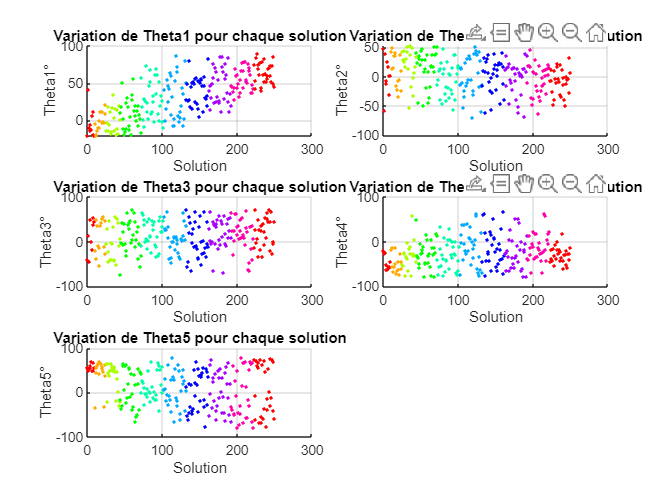

figure;
unique_colors_map = containers.Map('KeyType', 'double', 'ValueType', 'double');
color_index = 1;

for i = 1:size(resultats_finaux, 1)
    point_number = resultats_finaux(i, 1);
    if ~isKey(unique_colors_map, point_number)
        unique_colors_map(point_number) = color_index;
        color_index = color_index + 1;
    end
end

% Définir le nombre de lignes et de colonnes pour la grille
num_rows = 3; % Modifier le nombre de lignes selon le nombre de joints
num_cols = 2; % Nombre de colonnes pour afficher les graphiques

for joint = 1:5
    % Définir la position du subplot dans la grille
    subplot(num_rows, num_cols, joint);
    
    % Boucle sur chaque solution
    for i = 1:size(resultats_finaux, 1)
        point_number = resultats_finaux(i, 1); % Numéro de point
        color_index = unique_colors_map(point_number); % Récupérer l'index de couleur pour ce numéro de point

        % Définir la couleur en fonction de l'index récupéré
        color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]); % Utiliser l'espace colorimétrique HSV pour obtenir des couleurs distinctes

        % Tracer le point avec la couleur définie
        scatter(i, resultats_finaux(i, joint+1), 5, color, 'filled'); % Vous pouvez ajuster la taille du point (50) selon vos préférences
        hold on;
    end

    % Titre et étiquettes des axes
    title(['Variation de Theta', num2str(joint), ' pour chaque solution']);
    xlabel('Solution');
    ylabel(['Theta', num2str(joint), '°']);
    grid on;
end

### Variation de theta pour chaque solution avec une couleur pour chaque point de la trajectoire a suivre puis une forme pour chaque theta

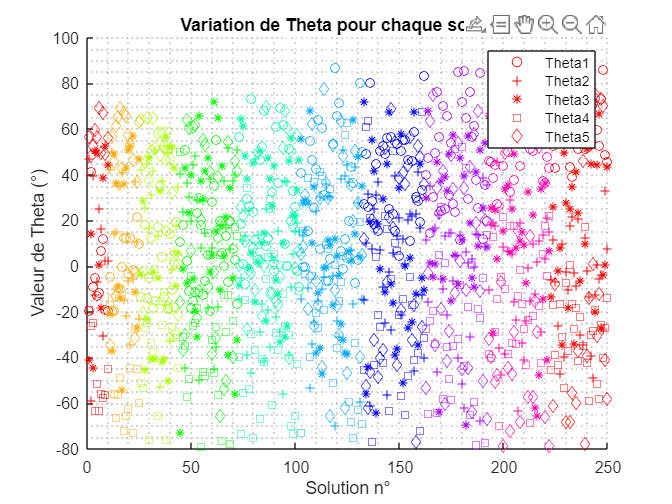

% Créer un tableau de hachage pour mapper chaque numéro de point à une couleur
unique_colors_map = containers.Map('KeyType', 'double', 'ValueType', 'double');
color_index = 1;

for i = 1:size(resultats_finaux, 1)
    point_number = resultats_finaux(i, 1); % Numéro de point
    if ~isKey(unique_colors_map, point_number)
        unique_colors_map(point_number) = color_index; % Assigner une nouvelle couleur pour chaque nouveau numéro de point
        color_index = color_index + 1;
    end
end

% Convertir les angles en degrés et ajuster les angles à l'intervalle [-180, 180]
final_results_deg = resultats_finaux(:, 2:6);

% Créer une nouvelle figure
figure;

% Boucle sur chaque solution
for i = 1:size(resultats_finaux, 1)
    point_number = resultats_finaux(i, 1); % Numéro de point
    
    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(point_number);

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le point avec la couleur définie et une forme différente pour chaque valeur de theta
    for joint = 1:5
        % Choisir la forme de marqueur en fonction de la valeur de theta
        switch joint
            case 1
                marker = 'o';
            case 2
                marker = '+';
            case 3
                marker = '*';
            case 4
                marker = 's';
            case 5
                marker = 'd';
        end

        % Tracer le point avec la couleur définie et la forme de marqueur appropriée
        scatter(i, final_results_deg(i, joint), 30, color, marker);
        hold on;
    end
end

% Titre et étiquettes des axes
title('Variation de Theta pour chaque solution');
xlabel('Solution n°');
ylabel('Valeur de Theta (°)');

% Légende
legend('Theta1', 'Theta2', 'Theta3', 'Theta4', 'Theta5');

% Afficher la grille
grid minor;

### Position pour chaque articulation, une couleur par point de la trajectoire

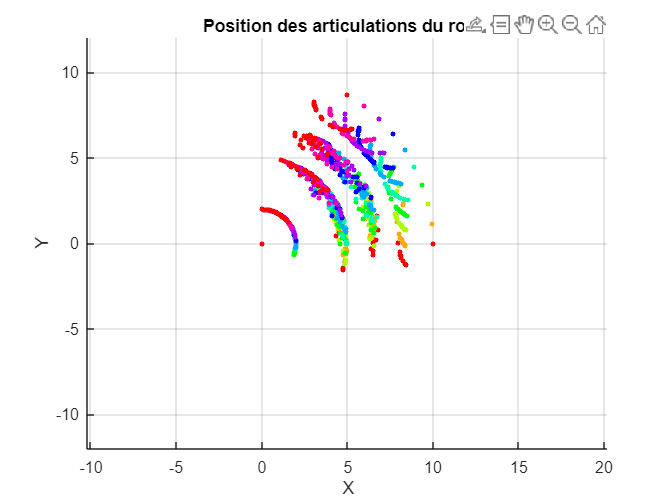


% Créer un tableau de hachage pour mapper chaque numéro de point à une couleur
unique_colors_map = containers.Map('KeyType', 'double', 'ValueType', 'double');
color_index = 1;

for i = 1:size(resultats_finaux, 1)
    point_number = resultats_finaux(i, 1); % Numéro de point
    if ~isKey(unique_colors_map, point_number)
        unique_colors_map(point_number) = color_index; % Assigner une nouvelle couleur pour chaque nouveau numéro de point
        color_index = color_index + 1;
    end
end

% Créer une nouvelle figure
figure;

hold on; % Garder le graphique actif pour ajouter les données de chaque solution

% Visualisation des configurations du robot
for i = 1:size(resultats_finaux, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = resultats_finaux(i, 2);
    theta2 = resultats_finaux(i, 3);
    theta3 = resultats_finaux(i, 4);
    theta4 = resultats_finaux(i, 5);
    theta5 = resultats_finaux(i, 6);

    % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
    O = [0, 0]; % Position de l'origine
    A = [a1*cosd(theta1), a1*sind(theta1)]; % Position de l'articulation A
    B = A + [a2*cosd(theta1+theta2), a2*sind(theta1+theta2)]; % Position de l'articulation B
    C = B + [a3*cosd(theta1+theta2+theta3), a3*sind(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
    D = C + [a4*cosd(theta1+theta2+theta3+theta4), a4*sind(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
    E = D + [a5*cosd(theta1+theta2+theta3+theta4+theta5), a5*sind(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)

    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(resultats_finaux(i, 1));

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le robot pour cette configuration 
    scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 10, color, 'filled'); % Marques pour les articulations
end 
grid on;

% Calculer les limites des axes
xlim([-12, 12]); 
ylim([-12, 12]);
axis equal

% Configurer le titre et les étiquettes des axes
title('Position des articulations du robot');
xlabel('X');
ylabel('Y');

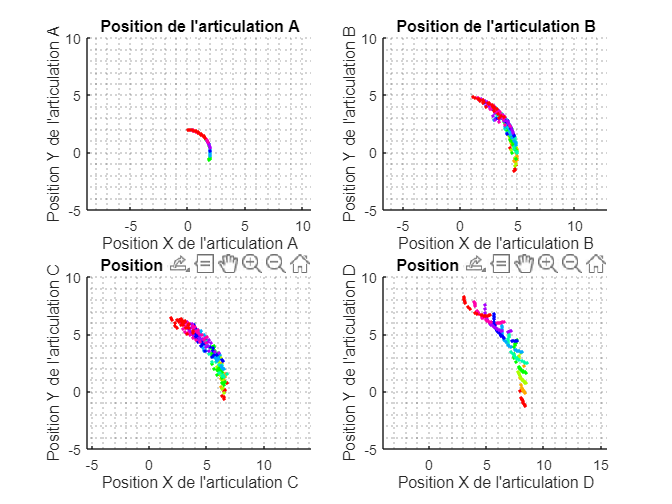




% Créer un graphique distinct pour chaque articulation
figure;

% Créer un tableau de hachage pour mapper chaque numéro de point à une couleur
unique_colors_map = containers.Map('KeyType', 'double', 'ValueType', 'double');
color_index = 1;

for i = 1:size(resultats_finaux, 1)
    point_number = resultats_finaux(i, 1); % Numéro de point
    if ~isKey(unique_colors_map, point_number)
        unique_colors_map(point_number) = color_index; % Assigner une couleur pour chaque nouveau numéro de point
        color_index = color_index + 1;
    end
end

% Articulation A
subplot(2, 2, 1);
title('Position de l''articulation A');
xlabel('Position X de l''articulation A');
ylabel('Position Y de l''articulation A');
hold on;
% Calculer les positions de l'articulation A pour chaque solution
A_positions = zeros(size(resultats_finaux, 1), 2);
for i = 1:size(resultats_finaux, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = resultats_finaux(i, 2);
    
    % Calculer la position de l'articulation A pour cette solution
    A = [a1*cosd(theta1), a1*sind(theta1)]; % Position de l'articulation A
    A_positions(i, :) = A;
    
    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(resultats_finaux(i, 1));

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le point avec la couleur définie
    scatter(A(1), A(2), 5, color, 'filled');
end
grid minor;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation B
subplot(2, 2, 2);
title('Position de l''articulation B');
xlabel('Position X de l''articulation B');
ylabel('Position Y de l''articulation B');
hold on;
% Calculer les positions de l'articulation B pour chaque solution
B_positions = zeros(size(resultats_finaux, 1), 2);
for i = 1:size(resultats_finaux, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = resultats_finaux(i, 2);
    theta2 = resultats_finaux(i, 3);
    
    % Calculer la position de l'articulation B pour cette solution
    B = A_positions(i, :) + [a2*cosd(theta1+theta2), a2*sind(theta1+theta2)]; % Position de l'articulation B
    B_positions(i, :) = B;
    
    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(resultats_finaux(i, 1));

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le point avec la couleur définie
    scatter(B(1), B(2), 5, color, 'filled');
end
grid minor;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation C
subplot(2, 2, 3);
title('Position de l''articulation C');
xlabel('Position X de l''articulation C');
ylabel('Position Y de l''articulation C');
hold on;
% Calculer les positions de l'articulation C pour chaque solution
C_positions = zeros(size(resultats_finaux, 1), 2);
for i = 1:size(resultats_finaux, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = resultats_finaux(i, 2);
    theta2 = resultats_finaux(i, 3);
    theta3 = resultats_finaux(i, 4);
    
    % Calculer la position de l'articulation C pour cette solution
    C = B_positions(i, :) + [a3*cosd(theta1+theta2+theta3), a3*sind(theta1+theta2+theta3)]; % Position de l'articulation C
    C_positions(i, :) = C;
    
    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(resultats_finaux(i, 1));

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le point avec la couleur définie
    scatter(C(1), C(2), 5, color, 'filled');
end
grid minor;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation D
subplot(2, 2, 4);
title('Position de l''articulation D');
xlabel('Position X de l''articulation D');
ylabel('Position Y de l''articulation D');
hold on;
% Calculer les positions de l'articulation D pour chaque solution
D_positions = zeros(size(resultats_finaux, 1), 2);
for i = 1:size(resultats_finaux, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = resultats_finaux(i, 2);
    theta2 = resultats_finaux(i, 3);
    theta3 = resultats_finaux(i, 4);
    theta4 = resultats_finaux(i, 5);
    
    % Calculer la position de l'articulation D pour cette solution
    D = C_positions(i, :) + [a4*cosd(theta1+theta2+theta3+theta4), a4*sind(theta1+theta2+theta3+theta4)]; % Position de l'articulation D
    D_positions(i, :) = D;
    
    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(resultats_finaux(i, 1));

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le point avec la couleur définie
    scatter(D(1), D(2), 5, color, 'filled');
end
grid minor;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Réglage des espacements entre les sous-graphiques
subplot(2, 2, 1); axis equal; 
subplot(2, 2, 2); axis equal; 
subplot(2, 2, 3); axis equal; 
subplot(2, 2, 4); axis equal;

function singularite = check_singularities(theta_solutions, a1, a2, a3, a4, a5)
    % Initialisation du vecteur indiquant la singularité pour chaque configuration
    singularite = false(size(theta_solutions, 1), 1);
  
    % Boucle sur toutes les solutions de theta
    for i = 1:size(theta_solutions, 1)
        % Extraire les valeurs de theta
        theta = theta_solutions(i, :);
        % Extraire les valeurs de theta individuellement
        theta1 = theta(1);
        theta2 = theta(2);
        theta3 = theta(3);
        theta4 = theta(4);
        theta5 = theta(5);
        
        % Calculer les dérivées partielles
        dx_dtheta1 = -a1*sin(theta1) - a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
        dx_dtheta2 = -a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
        dx_dtheta3 = a3*sin(theta3)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a4*sin(theta4)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a5*sin(theta5)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2));
        dx_dtheta4 = -a4*sin(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a5*sin(theta5)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2));
        dx_dtheta5 = -a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));

        dy_dtheta1 = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta2)*sin(theta1) + a2*cos(theta1)*sin(theta2) + a4*cos(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
        dy_dtheta2 = a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
        dy_dtheta3 = - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
        dy_dtheta4 = - a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
        dy_dtheta5 = a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) + sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));

        % Construire la Jacobienne
        J = [dx_dtheta1, dx_dtheta2, dx_dtheta3, dx_dtheta4, dx_dtheta5; 
             dy_dtheta1, dy_dtheta2, dy_dtheta3, dy_dtheta4, dy_dtheta5];
        
        % Vérifier le rang de la matrice jacobienne
        if rank(J) < min(size(J))
            % Indiquer que cette configuration est singulière
            singularite(i) = true;
        end
       
    end
end
